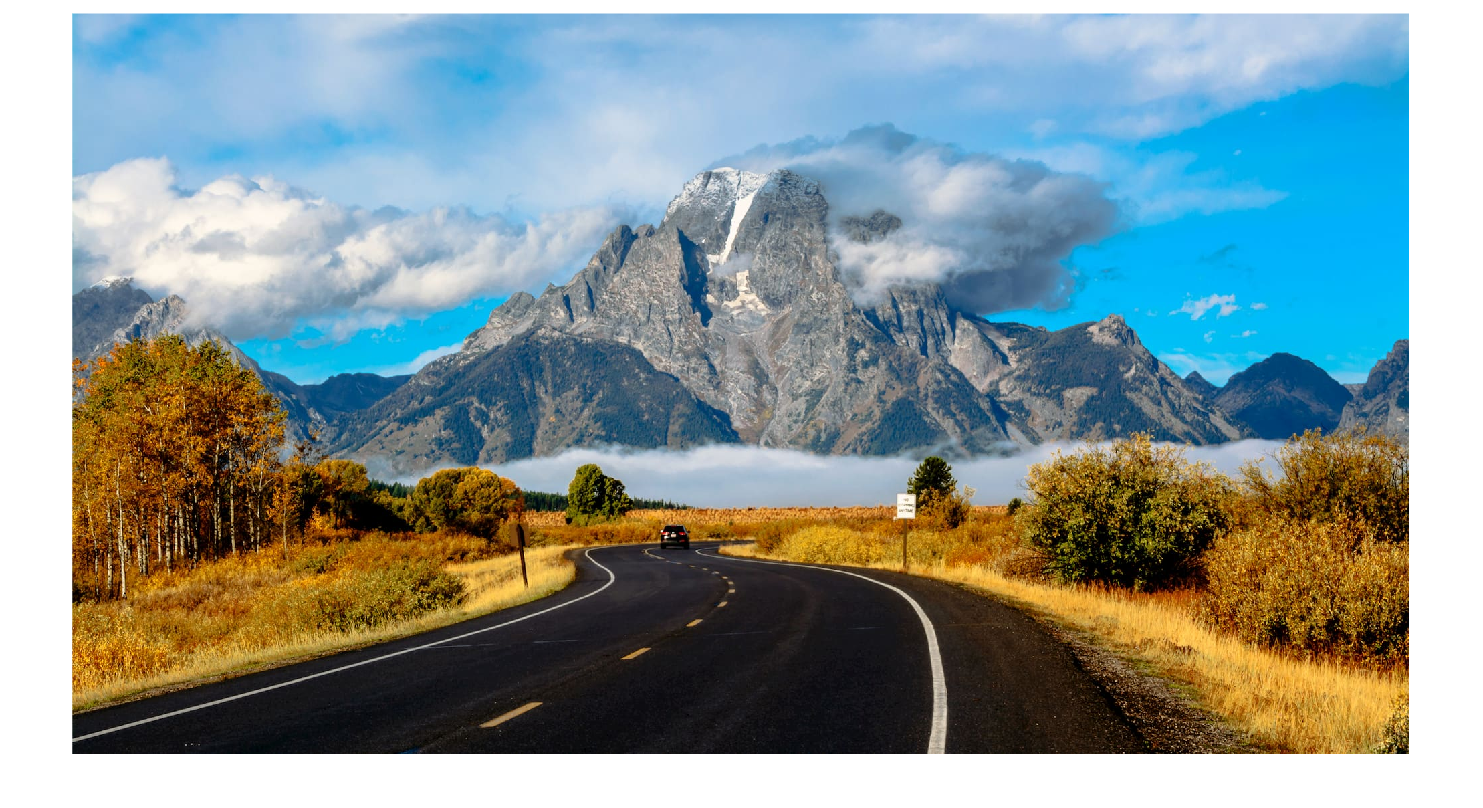

close; clear all; clc;

f_original = imread("Teton.jpeg");
f = f_original;
xdim = size(f,1);
ydim = size(f,2);
zdim = size(f,3);
imshow(f);

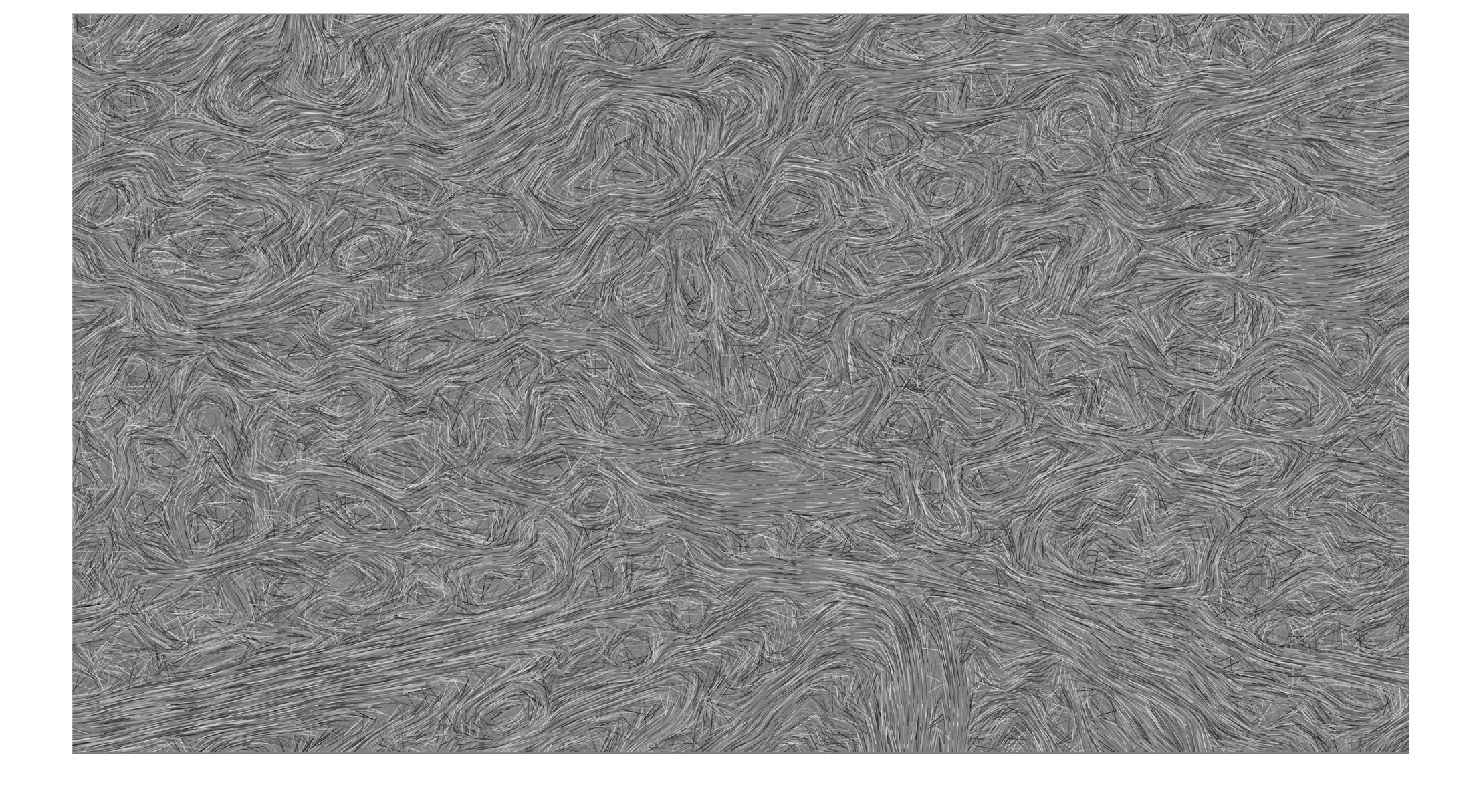

brush = imread("brush_teton.jpeg");
brush = imresize(brush, [xdim ydim]);
imshow(brush);

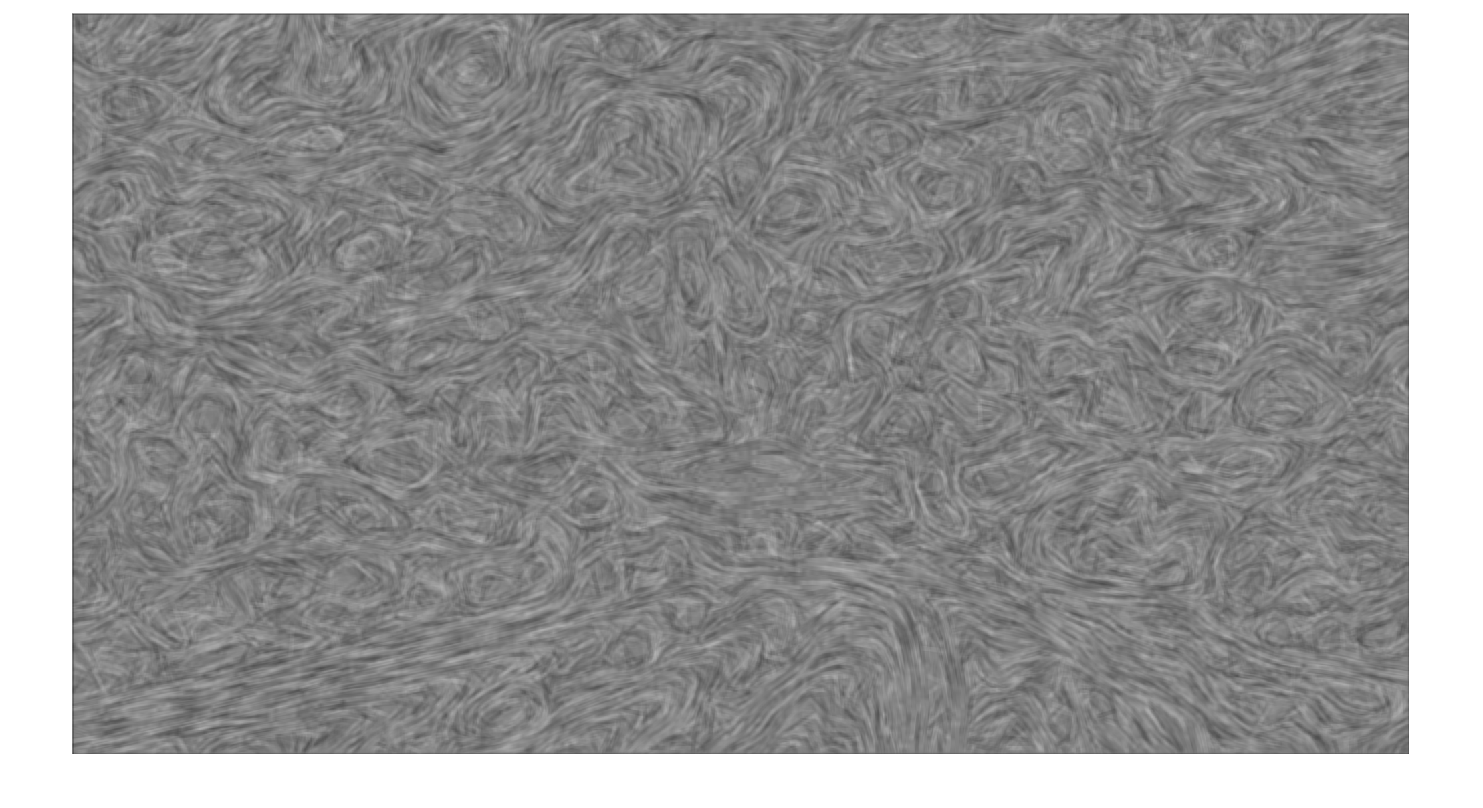

k = 7;
box_w = ones(k,k)./(k*k);
new_brush = imfilter(brush,box_w);
imshow(new_brush);

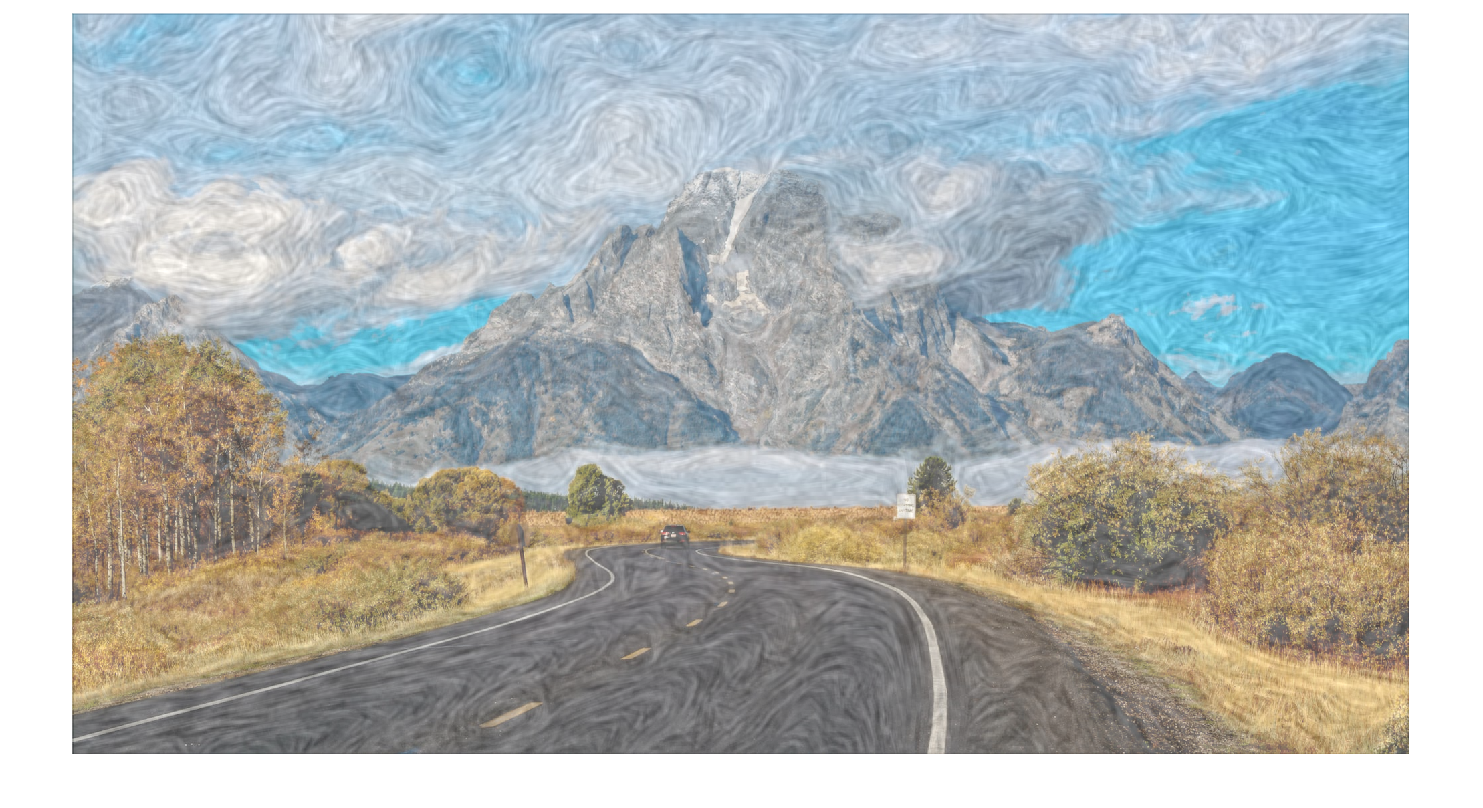

 
for i = 1:xdim
    for j = 1:ydim
        for k = 1:zdim
            f(i,j,k) = (0.5*f(i,j,k)+0.8*new_brush(i,j,k));
        end
    end
end
imshow(f);

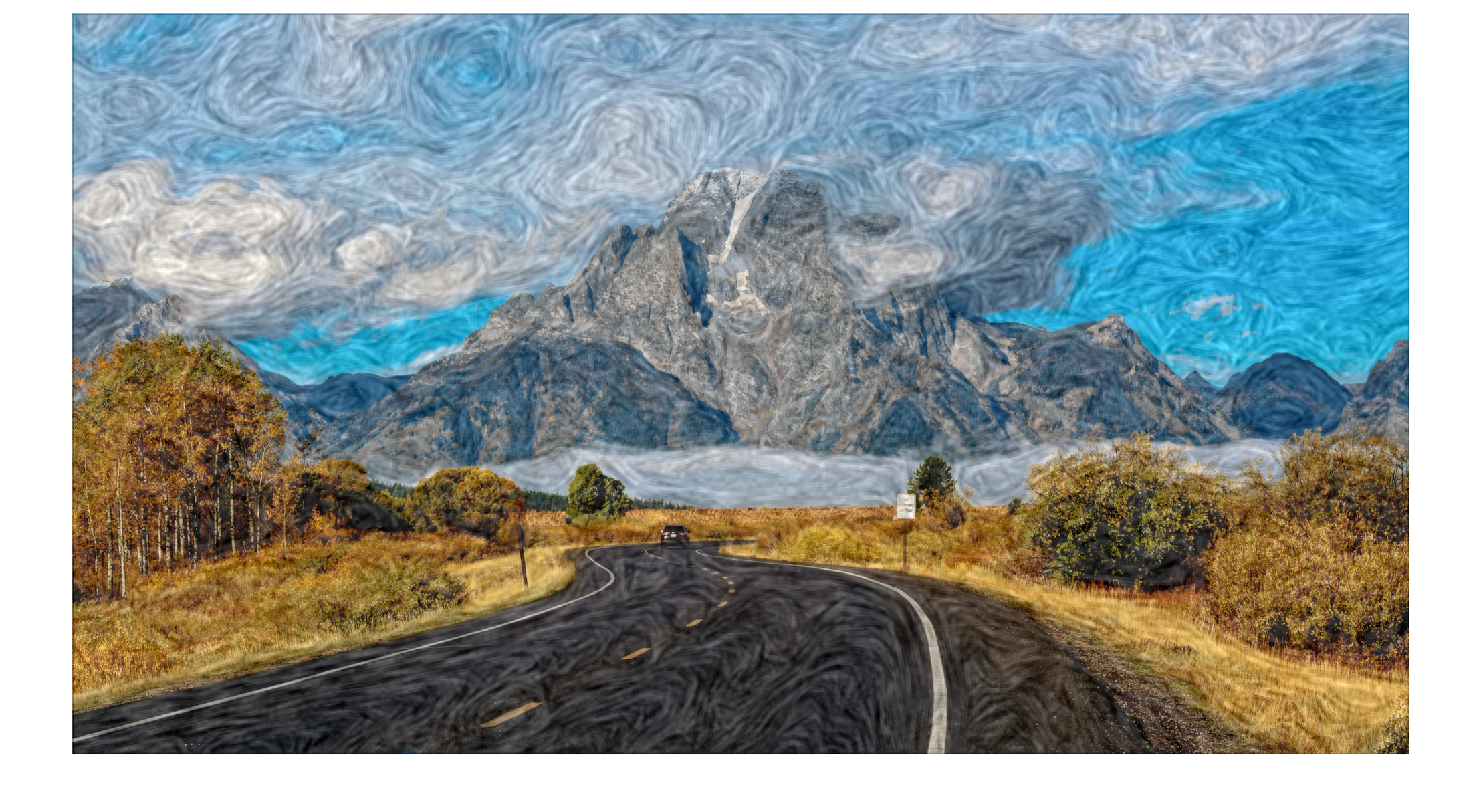

adjusted_f = imadjustn(f,[0.3 1],[0,1],1.02);
imshow(adjusted_f);

imshow(f_original);